## Load Preprocessed Data

clear all;
close all;

disp('Loading preprocessed data from kddcup_original_data_preprocessed.mat...');

Loading preprocessed data from kddcup_original_data_preprocessed.mat...


load('../Data/kddcup_original_data_preprocessed.mat', 'dataInputs', 'dataTargets');
disp('Data loaded successfully.');

Data loaded successfully.



% Display the original size of the dataset
totalSamples = size(dataInputs, 2);
disp(['Total number of samples: ', num2str(totalSamples)]);

Total number of samples: 4898431


## Prediction with best_feasible_model with the whole dataset

% Load trained model and test data
fprintf('Loading trained model from "Data/final_model_best_feasible.mat"...\n');

Loading trained model from "Data/final_model_best_feasible.mat"...


load('../Data/final_model_best_feasible.mat', 'net');
fprintf('Best Feasible Trained model loaded successfully.\n');

Best Feasible Trained model loaded successfully.



% Perform predictions on the test data
fprintf('Predicting on the test data...\n');

Predicting on the test data...


predictedTestOutputs = net(dataInputs);  % Raw outputs from network
predictedTestLabels = predictedTestOutputs >= 0.5;  % Convert to binary labels (assuming threshold of 0.5)

% Ensure both testTargets and predictedTestLabels are of type double
testTargets = double(dataTargets);
predictedTestLabels = double(predictedTestLabels);

% Calculate accuracy
numCorrect = sum(predictedTestLabels == testTargets);
accuracy = numCorrect / length(testTargets) * 100;
fprintf('Accuracy on Test Data: %.2f%%\n', accuracy);

Accuracy on Test Data: 99.72%



% Save accuracy in a text file
metricsFile = fopen('../outputs/matrix_best_feasible_with_unseendata.txt', 'w');
fprintf(metricsFile, 'Accuracy on Test Data: %.2f%%\n', accuracy);
fclose(metricsFile);

% Generate and save Confusion Matrix
fprintf('Generating confusion matrix...\n');

Generating confusion matrix...


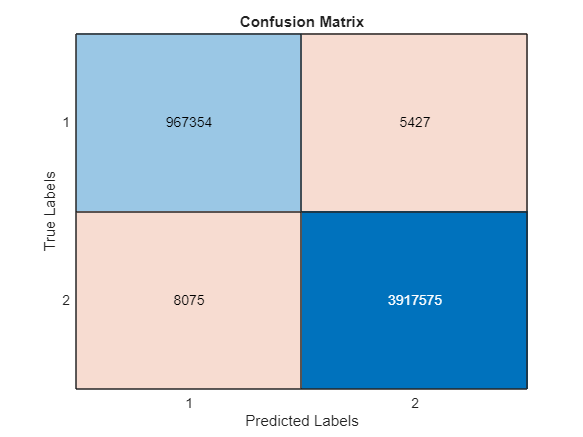

% Compute the rounded confusion matrix
confMat = round(confusionmat(testTargets, predictedTestLabels));

% Display the confusion matrix using confusionchart
figure;
cm = confusionchart(confMat);

% Set properties to show numbers without scientific notation
cm.CellLabelFormat = '%d';  % Format labels as integers

% Customize the chart title and labels as needed
cm.Title = 'Confusion Matrix';
cm.XLabel = 'Predicted Labels';
cm.YLabel = 'True Labels';

% Save the confusion matrix plot as a high-resolution PNG file
exportgraphics(gcf, '../outputs/confusion_matrix_best_feasible_with_unseendata.png', 'Resolution', 300);

fprintf('Confusion matrix saved as "outputs/confusion_matrix_best_feasible_with_unseendata.png" with high resolution.\n');

Confusion matrix saved as "outputs/confusion_matrix_best_feasible_with_unseendata.png" with high resolution.




% Calculate additional metrics (Precision, Recall, F1 Score)
truePositives = sum(predictedTestLabels == 1 & testTargets == 1);
trueNegatives = sum(predictedTestLabels == 0 & testTargets == 0);
falsePositives = sum(predictedTestLabels == 1 & testTargets == 0);
falseNegatives = sum(predictedTestLabels == 0 & testTargets == 1);

precision = truePositives / (truePositives + falsePositives);
recall = truePositives / (truePositives + falseNegatives);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 99.86%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 99.79%


fprintf('F1 Score: %.2f%%\n', f1Score * 100);

F1 Score: 99.83%



% Save additional metrics
metricsFile = fopen('../outputs/metrics_best_feasible_with_unseendata.txt', 'a');  % Open in append mode
fprintf(metricsFile, 'Precision: %.2f%%\n', precision * 100);
fprintf(metricsFile, 'Recall: %.2f%%\n', recall * 100);
fprintf(metricsFile, 'F1 Score: %.2f%%\n', f1Score * 100);
fclose(metricsFile);

% Generate ROC Curve and save
fprintf('Generating ROC curve...\n');

Generating ROC curve...


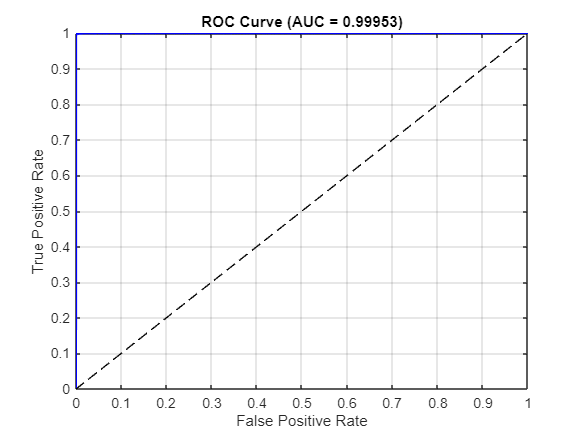

[X, Y, T, AUC] = perfcurve(testTargets, predictedTestOutputs, 1);
figure;
plot(X, Y, '-b', 'LineWidth', 1.5);
hold on;
plot([0 1], [0 1], '--k');  % Diagonal line for random guessing
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ', num2str(AUC), ')']);
grid on;

% Save the ROC curve as a high-resolution PNG file
exportgraphics(gcf, '../outputs/roc_curve_best_feasible_with_unseendata.png', 'Resolution', 300);

fprintf('ROC curve saved as "../outputs/roc_curve_best_feasible_with_unseendata.png" with high resolution.\n');

ROC curve saved as "../outputs/roc_curve_best_feasible_with_unseendata.png" with high resolution.
